# Stochastic Subspace Identification (SSI) of a Linear 4-DOF System

This example covers identification of a linear, four story shear building using the built-in `n4sid` algorithm as well as the `ssicov` and `ssidata` algorithms included in the OoMA toolbox. The example walks through the problem setup, calculation of modal parameters, identification of the system matrices using SSI, comparison of mode shape vectors, and comparison of output power spectrums.

## Introduction

Practical implementations of Stochastic Subspace Identification (SSI) are concerned with identification of discrete time systems having the form:


$$\mathbf{x}[k+1] = \mathbf{Ax}[k]+\mathbf{v}[k]\\
\mathbf{y}[k] = \mathbf{Cx}[k]+\mathbf{w}[k]$$


where $\mathbf{x}$ and $\mathbf{y}$ are the state and output vectors, $\mathbf{A}$ and $\mathbf{C}$ are the are the discrete state matrix and output matrix, and $\mathbf{v}$ and $\mathbf{w}$ are the state noise and output noise processes consisting of unmeasured Gaussian white noise.

The objective of SSI is to determine the system matrices $\mathbf{A}$ and $\mathbf{C}$ using only the measured output sequences $\mathbf{y}[k]$ by making certain assumptions about the statistical properties of $\mathbf{v}$ and $\mathbf{w}$.

## Set Up the Linear System

A model of a four story building will be used to demonstrate the usage of various SSI algorithms. Each of the building's floors $i=1,\dots ,4$ are represented as masses $m_i$ interconnected with springs $k_i$ and dampers $c_i$:

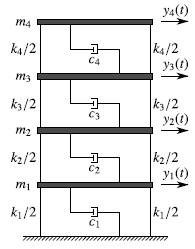

The equations of motion for the acceleration $\ddot{y_i}(t)$ of each floor in the structue are:


$$$$
\ddot{y_1}(t)=\frac{1}{m_{1}}\left(-k_{1}y_{1}-c_{1}\dot{y_{1}}+k_{2}(y_{2}-y_{1})+c_{2}(\dot{y_{2}}-\dot{y_{1}})\right)\\
\ddot{y_2}(t)=\frac{1}{m_{2}}\left(k_{2}(y_{1}-y_{2})+c_{2}(\dot{y_{1}}-\dot{y_{2}})+k_{3}(y_{3}-y_{2})+c_{3}(\dot{y_{3}}-\dot{y_{2}})\right)\\
\ddot{y_3}(t)=\frac{1}{m_{3}}\left(k_{3}(y_{2}-y_{3})+c_{3}(\dot{y_{2}}-\dot{y_{3}})+k_{4}(y_{4}-y_{3})+c_{4}(\dot{y_{4}}-\dot{y_{3}})\right)\\
\ddot{y_4}(t)=\frac{1}{m_{4}}\left(k_{4}(y_{3}-y_{4})+c_{4}(\dot{y_{3}}-\dot{y_{4}})\right)
$$$$


Rearranging the equations into state space form $\dot{\mathbf{x}}=\mathbf{Ax}$ gives:


$$\left[\matrix{
\dot{y_1}\cr
\dot{y_2}\cr
\dot{y_3}\cr
\dot{y_4}\cr
\ddot{y_1}\cr
\ddot{y_2}\cr
\ddot{y_3}\cr
\ddot{y_4}
}\right]
=
\left[\matrix{
0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\cr
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\cr
0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\cr
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\cr
\frac{-k_1-k_2}{m_1} & \frac{k_2}{m_1} & 0 & 0 & \frac{-c_1-c_2}{m_1} & \frac{c_2}{m_1} & 0 & 0\cr
\frac{k_2}{m_2} & \frac{-k_2-k_3}{m_2} & \frac{k_3}{m_2} & 0 & \frac{c_2}{m_2} & \frac{-c_2-c_3}{m_2} & \frac{c_3}{m_2} & 0\cr 0 & \frac{k_3}{m_3} & \frac{-k_3-k_4}{m_3} & \frac{k_4}{m_3} & 0 & \frac{c_3}{m_3} & \frac{-c_3-c_4}{m_3} & \frac{c_4}{m_3}\cr
0 & 0 & \frac{k_4}{m_4} & \frac{-k_4}{m_4} & 0 & 0 & \frac{c_4}{m_4} & \frac{-c_4}{m_4}
}\right]
\left[\matrix{
{y_1}\cr
{y_2}\cr
{y_3}\cr
{y_4}\cr
\dot{y_1}\cr
\dot{y_2}\cr
\dot{y_3}\cr
\dot{y_4}
}\right]$$


Assigning $m_i=10\mathrm{~kg}$, $k_i=10000 \mathrm{~Nm^{-1}}$, and $c_i=10\mathrm{~N(ms)^{-1}}$ to each floor yields the *continuous* time state matrix $\mathbf{A}_c$.

m = 10*ones(1,4);
k = 10000*ones(1,4);
c = 10*ones(1,4);
Ac = [
    0 0 0 0 1 0 0 0
    0 0 0 0 0 1 0 0
    0 0 0 0 0 0 1 0
    0 0 0 0 0 0 0 1
    [-k(1)-k(2) k(2) 0 0 -c(1)-c(2) c(2) 0 0]/m(1)
    [k(2) -k(2)-k(3) k(3) 0 c(2) -c(2)-c(3) c(3) 0]/m(2)
    [0 k(3) -k(3)-k(4) k(4) 0 c(3) -c(3)-c(4) c(4)]/m(3)
    [0 0 k(4) -k(4) 0 0 c(4) -c(4)]/m(4)
    ];

The discrete time state matrix $\mathbf{A}$ can be found using the matrix exponential, $\mathbf{A}=e^{\mathbf{A}_cT}$, where $T$ is the sampling period of the discrete system. For a sampling frequency of $f_s=50\mathrm{~Hz}$, the sampling period is $T=0.02\mathrm{~s}$.

fs = 50;
T = 1/fs;
A = expm(Ac*T);

If the accelerations of each floor are taken as the measured output of the system, the output matrix $\mathbf{C}$ is given as the last four rows of $\mathbf{A}_c$:

C = Ac(5:end,:);

## Modal Parameters of the Linear System

The modal parameters of a state space system can be determined from the system matrices $\mathbf{A}$ and $\mathbf{C}$ by performing eigenvalue decomposition and calculating the continuous time system poles $\lambda_n$:


$$\mathbf{A}=\mathbf{VDV}^{\top}\\
\mathbf{\Phi}=\mathbf{CV}\\
\lambda_n=\frac{\ln(D_n)}{T}\\
f_n=\frac{|\lambda_n|}{2\pi}\\
\zeta_n=\frac{\mathrm{Re}(\lambda_n)}{|\lambda_n|}$$


where $\mathbf{V}$ and $\mathbf{D}$ are the matrices containing the eigenvectors and eigenvalues $D_n$ of the state matrix $\mathbf{A}$, $\mathbf{\Phi}$ is the matrix containing the mode shape vectors $\mathbf{\phi}_n$, $f_n$ are the natural frequencies (in $\mathrm{Hz}$), and $\zeta_n$ are the modal damping ratios for modes $i=1,\ldots,n$.

The function `modalparams` in the OoMA toolbox calculates the modal parameters with complex-conjugate paired mode shapes eliminated and the modal parameters sorted in ascending frequency.

[fn,zeta,Phi] = modalparams(A,C,T);

Plot the mode shape vectors using the helper function `plotBuildingModes` included at the end of this example.

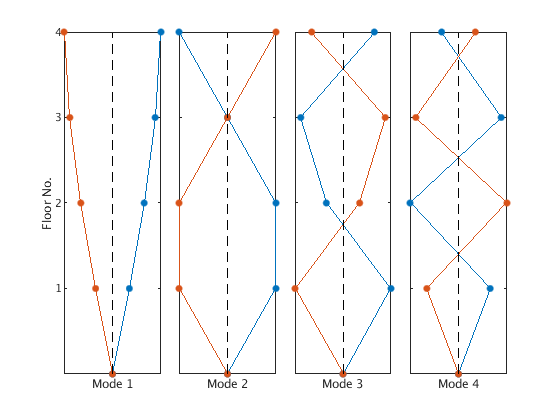

plotBuildingModes(Phi{1})

In general, mode shape vectors are complex-valued. The angle (or phase) of the mode shape vectors contains timing information and can cause the mode to "gallop" in time depending on the nature and extent of damping. See Appendix 1 for animations of the mode shapes in time.

## Discrete Time Simulation

For SSI purposes, white noise is input to each of the building's floors. Other operational data could be used, but care must be taken to ensure the input excitation does not add harmonics (i.e. additional eigenvalues) to the identified system.

Simulate the system for 100 seconds and set the state noise and output noise processes $\mathbf{v}$ and $\mathbf{w}$ to pull from random normal distributions.

t = 0:T:100;
Y = zeros(size(C,1),length(t));
rng(1) % control the random seed
v = 1e-2*randn(size(A,1),length(t));
w = 1e-3*randn(size(C,1),length(t));
x = zeros(size(A,1),1); % initial conditions
% step through time iteratively
for i = 1:length(t)
    Y(:,i) = C*x+w(:,i);
    x = A*x+v(:,i);
end

Plot the time histories as well as the power spectrums of the output using the built-in function `pwelch`.

[Syy,freqs] = pwelch(Y',[],[],[],fs); % obtain estimates of the output power spectrums
clf
subplot(2,1,1)
plot(t,Y)
xlabel('Time (s)')
ylabel('Acceleration (ms^{-2})')
axis tight
subplot(2,1,2)
plot(freqs,10*log10(Syy))
xlabel('Frequency (Hz)')
ylabel('PSD (dB)')
axis tight

Overlay the natural frequencies $f_n$ obtained from `modalparams` as vertical lines on the power spectrums.

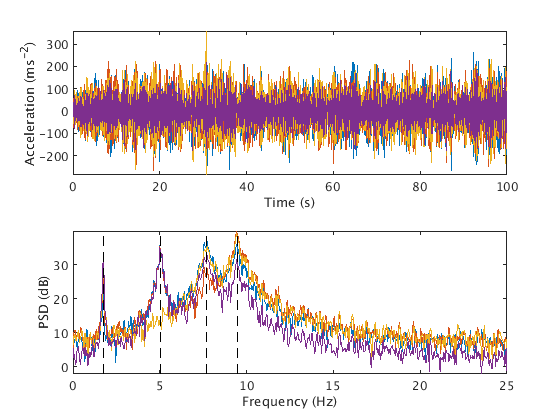

yl = ylim();
for i = 1:length(fn{1})
    line([fn{1}(i) fn{1}(i)],yl,'color','k','linestyle','--')
end

As expected, the time histories appear to be masked by white noise. The power spectrums; however, reveal four peaks that roughly correspond to the calculated natural frequencies $f_n$.

## Identification Using N4SID

First, create the data object for use with the built-in `n4sid` algorithm using `iddata`.

data = iddata(Y',[],T);

Call `n4sid` on the data object using a model order of 10 to overspecify the identified system and then extract the $\mathbf{A}$ and $\mathbf{C}$ matrices.

sys = n4sid(data,10);
[A_n4,~,C_n4,~] = ssdata(sys);

Obtain the modal parameters using the `modalparams` function from the OoMA toolbox.

[fn_n4,zeta_n4,Phi_n4] = modalparams(A_n4,C_n4,T);

Plot the identified mode shapes. Since only one model order was used for identification, use the first index of the cell array `Phi_n4`.

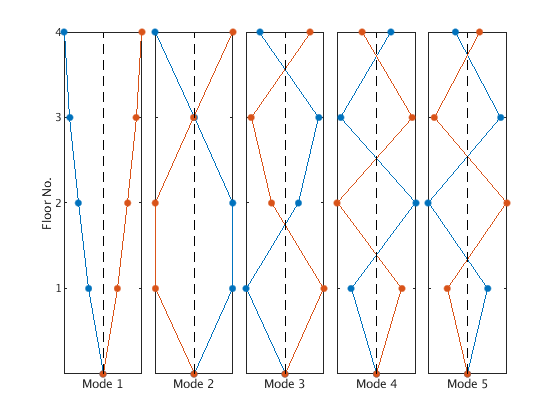

plotBuildingModes(Phi_n4{1})

As can be seen, an extra mode is obtained due to the overspecification of model order. In the next sections, the identification algorithms output information up to a maximum specified model order which will aid in determinination of an appropriate model order.

## Identification Using SSI-cov

Next, use the `ssicov` algorithm in the OoMA toolbox to identify the state space system from the simulated data.

Specify the maximum model order as 20 and use twice as many time lags as the model order for identification purposes.

order = 20;
s = 2*order;

Call `ssicov` on the output data.

[A_cov,C_cov,G_cov,R0_cov] = ssicov(Y,order,s);

SSI-cov status:
  forming block Hankel matrix...
  performing singular value decomposition...
  generating system matrices A,C,G for 20 model orders...
SSI-cov finished.


`ssicov` returns cell arrays for the system matrices, where the index of each cell array corresponds to the model order.

Create a stabilization diagram using the function `plotstab` included in the OoMA toolbox to aid in selection of stable poles and model order. Use a stabilization criteria of 1% error in frequency, 5% error in damping, and 98% confidence in mode shape vectors.

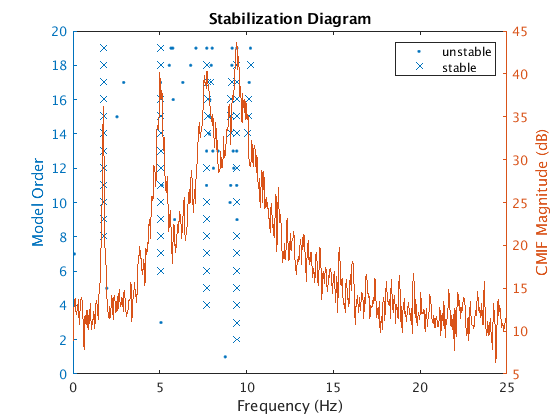

err = [0.01,0.05,0.98];
[IDs_cov] = plotstab(A_cov,C_cov,Y,T,[],err);

The stabilization diagram shows four alignments that are all present at a minimum model order of 8. The cell array `IDs_cov` contains the indices of the valid (stable) poles from the stabilization diagram.

Plot the mode shapes of only the stable poles (using `IDs_cov` for indexing) for a model order of 8.

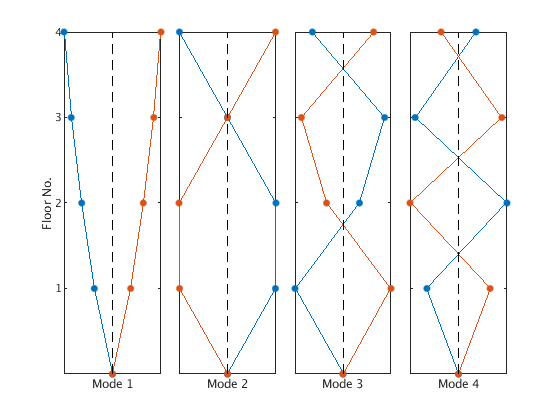

[fn_cov,zeta_cov,Phi_cov] = modalparams(A_cov,C_cov,T);
plotBuildingModes(Phi_cov{8}(:,IDs_cov{8}))

Qualitativley, the mode shapes are similar (but not identitical) to the analytic mode shapes obtained from the definition of the linear system. In the Comparison section, the Modal Assurance Criterion (MAC) will be used to quantify similarity between sets of mode shape vectors.

## Identification Using SSI-data

Keep the model order and number of time lags the same as what was used for `ssicov`. Call the function `ssidata` on the output data.

[A_data,C_data,G_data,R0_data] = ssidata(Y,order,s);

SSI-data status:
  forming shifted data matrix...
  projecting raw data...
  performing singular value decomposition...
  generating system matrices A,C,G for 20 model orders...
SSI-data finished.


Create a stabilization diagram using `plotstab` to aid in identification of stable poles and selection of model order. Use the same stabilization criteria as before.

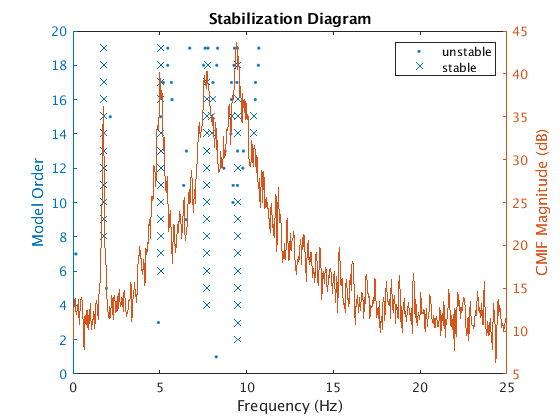

[IDs_data] = plotstab(A_data,C_data,Y,T,[],err);

Again, four alignments are identified that appear at a minimum model order of 8.

Plot the mode shapes of only the stable poles for a model order of 8.

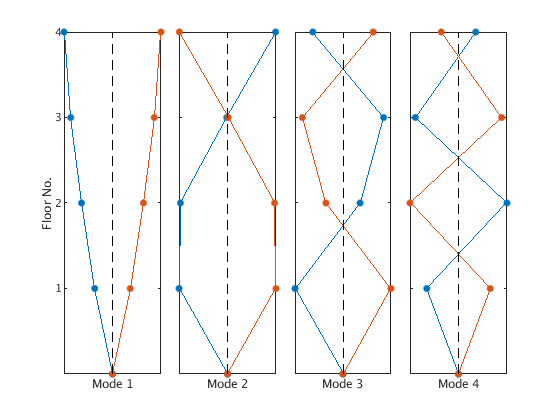

[fn_data,zeta_data,Phi_data] = modalparams(A_data,C_data,T);
plotBuildingModes(Phi_data{8}(:,IDs_data{8}))

## Mode Shape Comparison

The Modal Assurance Criterion (MAC) provides a measure of similarity between two mode shape vectors $\mathbf{\phi}_a$ and $\mathbf{\phi}_b$. The MAC is defined as:


$${MAC}_{a,b}=\frac{|\mathbf{\phi}_a^{\top}\mathbf{\phi}_b^*|^2}{\mathbf{\phi}_a^{\top}\mathbf{\phi}_a^*\mathbf{\phi}_b^{\top}\mathbf{\phi}_b^*}$$


and returns a scalar value in the range 0 to 1, where a value of 1 indicates perfect consistency between the two mode shapes. The modal assurance criterion is implemented in the OoMA toolbox functions `mac` and `macmatrix`.

First, generate the MAC matrix between the actual mode shape vectors and those identified using the `n4sid` function.

mm_n4 = macmatrix(Phi{1},Phi_n4{1})

mm_n4 =     0.9992    0.0000    0.0000    0.0000    0.0003
    0.0001    0.9997    0.0000    0.0000    0.0074
    0.0006    0.0001    0.9996    0.0003    0.0163
    0.0002    0.0002    0.0004    0.9997    0.9759


Display the MAC values in the matrix using `imagesc`.

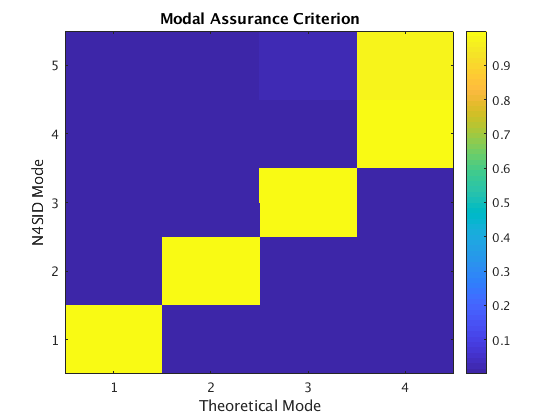

macplot(mm_n4)
xlabel('Theoretical Mode')
ylabel('N4SID Mode')

There is excellent agreement in the first four modes. Since the model was overspecified, the 5th mode appears to be a largely a replicate of the 4th mode.

Now find the MAC matrix between the actual mode shapes and those found with `ssicov` and `ssidata` at a model order of 8, using only the poles that were valid in the stabilization diagrams.

mm_cov = macmatrix(Phi{1},Phi_cov{8}(:,IDs_cov{8}))

mm_cov =     0.9990    0.0000    0.0000    0.0000
    0.0001    0.9995    0.0000    0.0000
    0.0007    0.0001    0.9992    0.0001
    0.0002    0.0004    0.0007    0.9998


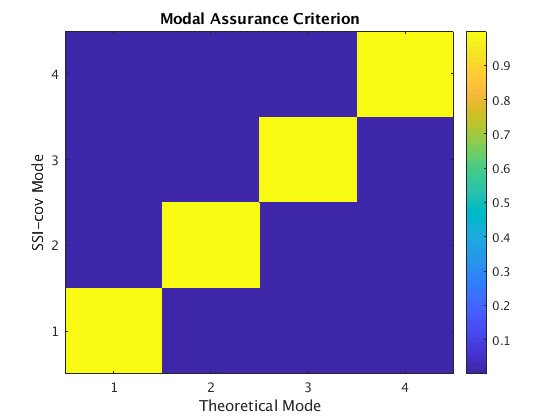

macplot(mm_cov)
xlabel('Theoretical Mode')
ylabel('SSI-cov Mode')


mm_data = macmatrix(Phi{1},Phi_data{8}(:,IDs_data{8}))

mm_data =     0.9993    0.0000    0.0000    0.0000
    0.0001    0.9996    0.0000    0.0000
    0.0004    0.0000    0.9995    0.0005
    0.0002    0.0004    0.0005    0.9995


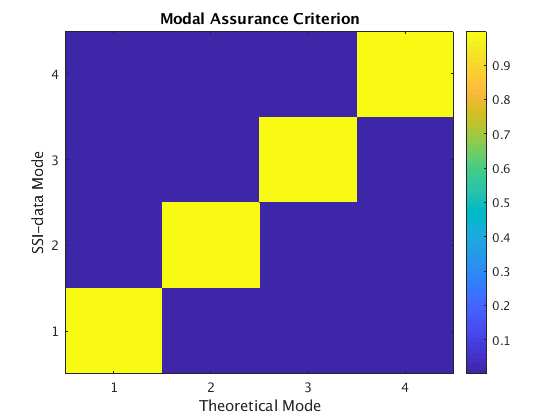

macplot(mm_data)
xlabel('Theoretical Mode')
ylabel('SSI-data Mode')

In all, there is excellent agreement among the sets of identified mode shape vectors and the theoretical mode shape vectors.

## Output Power Spectrums

The OoMA toolbox also provides the ability to generate output spectrums from the identified system matrices. The output power spectrum $\mathbf{S}_{yy}(z)$ of a stochastic system is defined as:


$$\mathbf{S}_{yy}(z)=\mathbf{C}(z\mathbf{I}-\mathbf{A})^{-1}\mathbf{G}+\mathbf{R}_0+\mathbf{G}^{\top}(z^{-1}\mathbf{I}-\mathbf{A}^{\top})^{-1}\mathbf{C}^{\top}\vert_{z=e^{i\omega T}}$$


where $\mathbf{R}_0$ is the zero lag output covariance matrix, $\mathbf{G}$ is the next state output covariance matrix, and $\omega$ is the circular frequency in units of $\mathrm{rad/s}$. The function `ssispectrum` takes the identified system matrices as well as the sampling period, model order, and number of frequency points as input. Note that `ssispectrum` returns normalized output spectrums, since the scaling of the output cannot be determined due to the input to the system being unmeasured.

Use `ssispectrum` to generate power spectrums for the models identified from `ssicov` and `ssidata` at a model order of 8 using 1000 frequency points. Also generate and normalize the output spectrum matrix from the simulated system using MATLAB's `cpsd` function.

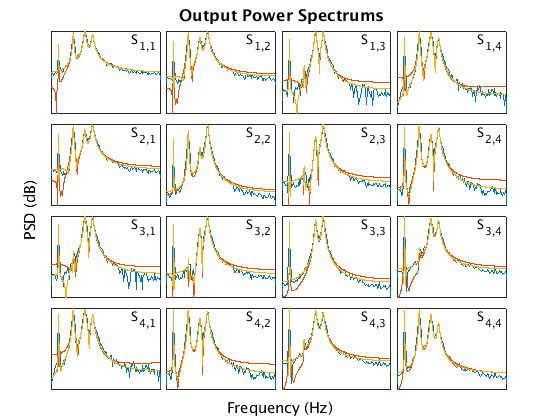

sel_order = 8; % selected model order
n = 1000; % number of frequency points
[Syy_cov,F] = ssispectrum(A_cov,C_cov,G_cov,R0_cov,T,sel_order,n);
[Syy_data,~] = ssispectrum(A_data,C_data,G_data,R0_data,T,sel_order,n);
win = hann(round(length(Y)/20)); % window to use for the welch PSD estimate in cpsd
[Syy,f] = cpsd(Y',Y',win,[],[],fs,'mimo'); % the simulated power spectrums
Syy = Syy/max(abs(Syy(:))); % normalize
clf
idx = 1;
for i = 1:size(Syy_cov,1)
    for j = 1:size(Syy_cov,2)
        % plot the different power spectrums
        subplot(size(Syy_cov,1),size(Syy_cov,2),idx)
        plot(f,10*log10(squeeze(abs(Syy(:,i,j)))))
        hold on
        plot(F,10*log10(squeeze(abs(Syy_cov(i,j,:)))))
        plot(F,10*log10(squeeze(abs(Syy_data(i,j,:)))))
        hold off
        axis tight
        % remove axis ticks and resize axes
        inset =  get(gca,'tightinset');
        pos = get(gca,'position');
        set(gca,'position',[pos(1)-inset(1) pos(2)-inset(2) pos(3)+inset(1) pos(4)+inset(2)])
        xticks([])
        yticks([])
        idx = idx+1;
        % label the indices of the cross spectrum
        xl = xlim;
        yl = ylim;
        text(xl(2),yl(2),['S_{' num2str(i) ',' num2str(j) '} '],'horizontalalignment','right','verticalalignment','top')
    end
end
% create x and y labels for the matrix of subplots
H = axes('units','normalized','position',[0 0 1 1],'visible','off');
text(0.5,.05,'Frequency (Hz)','HorizontalAlignment','center','VerticalAlignment','top','FontSize',11)
text(0.07,0.5,'PSD (dB)','Rotation',90,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',11)
text(0.5,.94,'\bf Output Power Spectrums','HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12)

The matrix of power spectrums shows that the identified systems match well at the peaks and that there are deviations in the toughs. The system obtained using `ssidata` (yellow) appears to match the simulated output power spectrum more closely than the system obtained using `ssicov` (red). Note that the number of time lags and model order could have a strong influence on the shape of the output power spectrums and would be of interest for a more in-depth investigation into fitting a model to the simulated data.

## Concluding Remarks

This example demonstrated the use of various system identification algorithms for determining the natural frequencies, damping ratios, and mode shapes of a simulated 4 story building under random excitation. The modal parameters of the structure were successfully recovered, highlighting the utility of output-only identification when the input excitation is difficult to measure or control. Of note is the information provided by the stabilization diagram using the OoMA toolbox function `plotstab`, which is not a feature provided in the classical system identification toolbox included with MATLAB for output-only modal analysis. Looping could be used to save system realizations at varying model orders for an identification algorithm like `n4sid`, but such an implementation is costly in compute time (not to mention the system ID algorithms in MATLAB already include something similar when leaving model order unspecified) whereas the functions `ssicov` and `ssidata` make use of tuncated models to generate the stabilization diagram and provide system realizations across the range of specified model orders at relatively low comptational expense.

## Appendix 1: Mode Shape Vector Animations

The helper function `animateBuildingModes` generates animated GIFs of the provided mode shape vectors.

animateBuildingModes(Phi{1},1:4,'Theoretical')

animation saved to file "Theoretical modes 1 to 4.gif"


animateBuildingModes(Phi_n4{1},1:4,'N4SID')

animation saved to file "N4SID modes 1 to 4.gif"


animateBuildingModes(Phi_cov{8}(:,IDs_cov{8}),1:4,'SSI-cov')

animation saved to file "SSI-cov modes 1 to 4.gif"


animateBuildingModes(Phi_data{8}(:,IDs_data{8}),1:4,'SSI-data')

animation saved to file "SSI-data modes 1 to 4.gif"


Below are the animated GIFs obtained from running `animateBuildingModes` on the obtained sets of mode shapes.

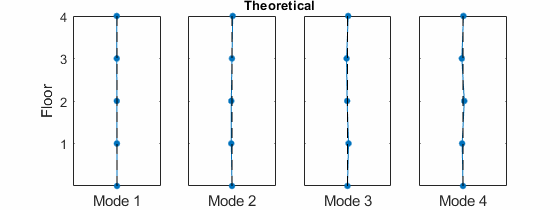

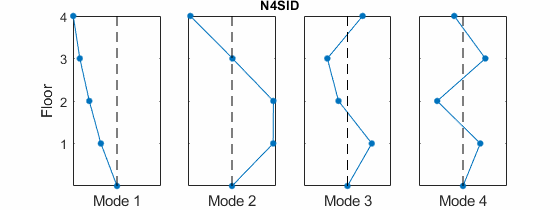

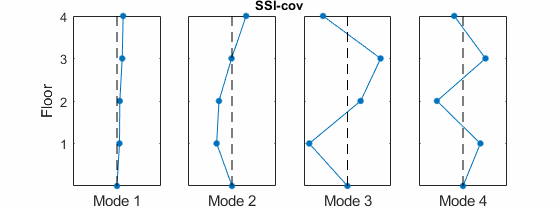

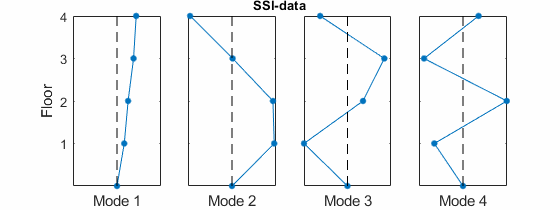

Visually, the mode shapes are all very similar across the different identification methods, which is consistent with the MAC matrices.

## Appendix 2: Helper Functions

***plotBuildingModes(Phi)***

A helper function for plotting the mode shapes of the simulated 4 story building. The maximum displacement generated by the mode shape is used for display. In general, complex mode shapes must be visualized in time as an animation to effectively capture the contribution of damping to the mode shape and any "travelling" components.

function plotBuildingModes(Phi)
clf
for i = 1:size(Phi,2)
    subplot(1,size(Phi,2),i)
    z = Phi(:,i);
    phase = [cos(angle(z)) sin(angle(z))]; % the angles of the mode shape vector
    % choose the mode shape phase that maximizes the displacement
    [~,idx] = max([sum(abs(phase(:,1))) sum(abs(phase(:,2)))]);
    shape = abs(z).*phase(:,idx);
    plot([0; shape],0:size(Phi,1),'.-','markersize',15)
    hold on
    % plot the 'other side' of the mode shape
    plot([0; -shape],0:size(Phi,1),'.-','markersize',15)
    % plot the building centerline
    line([0 0],[0 size(Phi,1)],'color','k','linestyle','--')
    hold off
    yticks(1:size(Phi,1))
    xticks([])
    % remove axis ticks and resize axes
    inset =  get(gca,'tightinset');
    pos = get(gca,'position');
    set(gca,'position',[pos(1)-inset(1) pos(2)-inset(2) pos(3)+inset(1) pos(4)+inset(2)])
    if i == 1
        ylabel('Floor No.') % only label the x-axis at the first plot
    else
        yticklabels([])
    end
    xlabel(['Mode ' num2str(i)])
    axis tight
end
end

***animateBuildingModes(Phi,modeRange,filePrefix)***

A helper function for generating animated GIFs of mode shape vectors for the shear building simulation used in this example.

function animateBuildingModes(Phi,modeRange,filePrefix)
fps = 60; % frames per second for the gif
t = 0:1/fps:(1-1/fps); % animate over 1 second
zt = zeros(size(Phi,1),length(t),length(modeRange));
clf
set(gcf,'color','w','units','inches','paperpositionmode','auto')
pos = get(gcf,'position');
set(gcf,'position',[pos(1) pos(2) pos(3) pos(4)/2]) % half the default height
mode_shape = cell(1,length(modeRange));
for i = 1:length(modeRange)
    z = Phi(:,i);
    zt(:,:,i) = abs(z).*cos(2*pi*t+angle(z)); % the displacement trajectory at 1 cylce/sec (2*pi rad/sec)
    subplot(1,length(modeRange),i) % not recommended to use more than ~5 mode shapes with this subplot arrangement
    mode_shape{i} = plot([0;zt(:,1)],0:size(zt,1),'.-','markersize',15);
    yl = ylim;
    line([0 0],yl,'color','k','linestyle','--') % reference zero displacement line
    xlim([-max(abs(z(:))) max(abs(z(:)))])
    yticks(1:size(z,1))
    xticks([])
    if i == 1
        ylabel('Floor')
    else
        yticklabels([])
    end
    xlabel(['Mode ' num2str(modeRange(i))])
    % title for the whole group of subplots
    axes('position',[0 0 1 1],'visible','off')
    text(0.5,.94,['\bf' filePrefix],'horizontalalignment','center','VerticalAlignment','bottom')
end
filename = [filePrefix ' modes ' num2str(modeRange(1)) ' to ' num2str(modeRange(end)) '.gif'];
for i = 1:length(t)
    for j = 1:length(modeRange)
        mode_shape{j}.XData = [0;zt(:,i,j)]; % update the line data for each plot
    end
    % grab the frame and add it to the animated gif
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    if i == 1
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf,'delaytime',1/fps);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append','delaytime',1/fps);
    end
end
close % dont display the figure
disp(['animation saved to file "' filename '"'])
end